# Ariadna Cortés Danés - Exercici 2 (Parcial 2)

**Resolució d'equacions. Convergència dels mètodes iteratius**

L'equació  $$ (x-1)^^3+\frac{6}{\sqrt{x^2+1}}=0$$ té una arrel real.    

**Es demana:**

**Q1)**  Comproveu que l'equació  $$ (x-1)^^3+\frac{6}{\sqrt{x^2+1}}=0$$  té una arrel real a l'interval [−3,3].  Determineu un interval $$J_\alpha =[a,b]$$ de longitud 0.5 que contingui **la única** solució.

% per a comprovar que l'equació té una única arrel, ho farem graficament
f = @(x) (x-1).^3 + 6./sqrt(x.^2+1)

f = function_handle with value:
    @(x)(x-1).^3+6./sqrt(x.^2+1)


x = [-3:0.1:3]

x =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


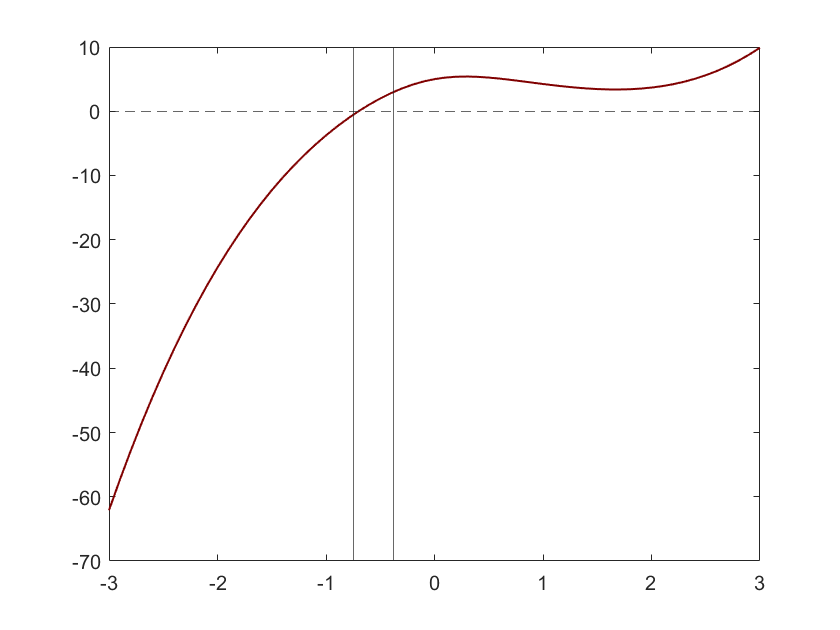


% per trobar l'interval que conté la solució, ho farem mitjançant el mètode
% de la biseccio
a = 3;
b = -3;
while abs(a-b) >= 0.5
    c = (a + b)/2;
    fa = feval(f,a); fc = feval(f,c); 
    if fc*fa < 0; b = c; else a = c; end
end


plot(x,f(x), 'Color', [0.5 0 0], 'LineWidth',1)
yline(0, '--')
xline(a)
xline(b)


% el metode de la biseccio ens tornarà un interval a,b tal que f(a)*f(b) <
% 0 i l'interval [a b] tindra com a màxim tamany 0.5
J = [a b]

J =    -0.3750   -0.7500


- **Resposta:** Gràfica, taula de valors i interval Jα=[a,b]

**Q2)**   Determineu l'arrel pel mètode de la secant, preneu  $$tol=0.5\cdot 10^{-8} $$i deixeu un màxim de 20 iteracions. Quantes iteracions calen?  

tol = 0.5*10^(-8);
itmax = 20;
[xk,fk,n] = secant(a, b,tol,itmax,f);

% tindrem per tant, la llista de aproximacions succesives xk, amb els seus
% corresponents valors fk, en un total de n iteracions. Per tant, les
% tolerancies buscades son

% nombre d'iteracions
n 

n = 5


% darrer iterat
xk(end)

ans = -0.7002


% tol = | x_n - x_{n_1}|
tolx = abs(diff(xk))

tolx =     0.3750    0.0586    0.0086    0.0002    0.0000    0.0000



% tol = |f(x_n)|
tolf = abs(fk)

tolf =     3.0184    0.5594    0.0968    0.0022    0.0000    0.0000         0


- **Resposta:** Nombre d'iteracions n, darrer iterat calculat $$x_n$$,  valor  $$tol_x=|x_n-x_{n-1}|$$ i  valor $$ tolf=|f(x_n)|$$.

**Q3) **  Els mètodes iteratius $$x_{n+1}=g(x_n)$$, definits per $$ x_0 \in J_\alpha $$ i si n>0  llavors  $$x_{n+1} = 1 - \left( \frac{6}{\sqrt{x_n^2+1}}\right)^{1/3}$$ i  $$x_{n+1} = -\sqrt{\frac{36}{(x_n-1)^6}-1}$$són convergents a l'arrel de l'equació inicial? 

c  = (a+b)/2;
[xk,fk,n1] = metodeIteracio1(c,tol,100,f);
xk(end)

ans = -0.7002


[xk,fk,n2] = metodeIteracio2(c,tol,100,f);
xk(end)

ans = -0.0179 - 1.0410i


% podem observar que el primer mètode si que convergeix a la solucio
% esperada, mentre que el segon no ho fa.

Considereu $$  J_\alpha $$ de l'apartat Q1 i calcula g′(x) per $$ x \in J_\alpha $$ emprant la formula de derivació endavant i h≤0.1

g1 = @(x)  1-(6./sqrt(x.^2+1)).^(1/3);
g2 = @(x) -sqrt((36./(x-1).^6) -1);
d1 = derivative(g1,x);
d2 = derivative(g2,x);
T = array2table([x' d1' d2'],"VariableNames",{'x','Derivada de g1(x)', 'Derivada de g2(x)'});
disp(T)

     x      Derivada de g1(x)      Derivada de g2(x)   
    ____    _________________    ______________________

      -3          -0.1238                  0-0.006621i 
    -2.9         -0.12847                  0-0.0079106i
    -2.8         -0.13342                  0-0.0094963i
    -2.7         -0.13867                  0-0.011457i 
    -2.6         -0.14423                  0-0.013897i 
    -2.5         -0.15013                  0-0.016953i 
    -2.4         -0.15639                  0-0.020806i 
    -2.3         -0.16302                  0-0.025702i 
    -2.2         -0.17003                  0-0.031973i 
    -2.1         -0.17745                  0-0.040076i 
      -2         -0.18528                  0-0.05065i  
    -1.9         -0.19351                  0-0.064595i 
    -1.8         -0.20212                  0-0.083211i 
    -1.7         -0.21108                  0-0.10841i  
 


% veiem que la derivada de g2 de x no existeix (no es real en tots els
% punts de l'interval J = [a b], motiu pel qual el metode no convergeix.

- **Resposta:** Taula de valors de g′(x) per $$ x_0 \in J_\alpha $$, a més raona i argumenta la resposta a la pregunta de l'enunciat Q3.

function [xk,fk,it] = secant(a, b,tol,itmax,fun)
    xk = [a b];
    fk = [fun(a) fun(b)];
    ek = 1;
    it = 0;
    
    while ek > tol && it < itmax
        x = xk(end) - fun(xk(end))*(xk(end)-xk(end-1))/( fun(xk(end))- fun(xk(end-1)));
        
        ek = abs(x - xk(length(xk))); 
        xk = [xk x];
        fk = [fk fun(x)];
        it = it + 1;
    end
end

function [xk,fk,it] = metodeIteracio1(c,tol,itmax,fun)
    xk = [c];
    fk = [fun(c)];
    ek = 1;
    it = 0;
    
    while ek > tol && it < itmax
        x = 1-(6/sqrt(xk(end)^2+1))^(1/3);
        
        ek = abs(x - xk(length(xk))); 
        xk = [xk x];
        fk = [fk fun(x)];
        it = it + 1;
    end
end

function [xk,fk,it] = metodeIteracio2(c,tol,itmax,fun)
    xk = [c];
    fk = [fun(c)];
    ek = 1;
    it = 0;
    
    while ek > tol && it < itmax
        x = -sqrt((36/(xk(end)-1)^6) -1);
        
        ek = abs(x - xk(length(xk))); 
        xk = [xk x];
        fk = [fk fun(x)];
        it = it + 1;
    end
end

function [puntprima] = derivative(fun, punt)
    delta = 10e-6;
    f0 = fun(punt);
    f1 = fun(punt + delta);
    puntprima = (f1 - f0)/delta;
end